s1 = readtable('first1v1.csv');
s1 = table2array(s1);
x = s1(2:end)

x = 1.0e+03 *

    0.0000    0.0000    0.0270    0.0026    3.1441    0.0010    0.0280


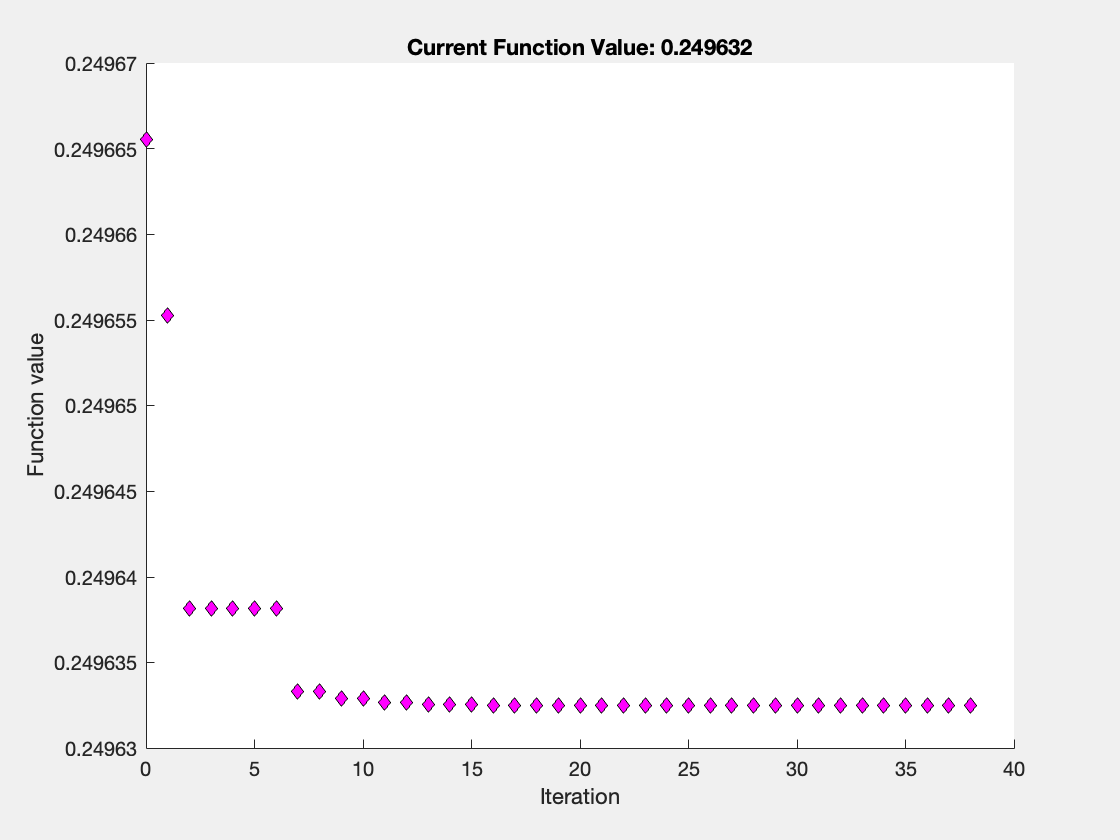



h = 0.01;
ti = 0:h:dpi(end); 
init = [10^4 0 10^-3];

options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 2000);
JJ = @(k) J(k,x, ti,init,h, dpi,y); 
[bk,fval] = fminsearch(JJ,x(3),options);


bk

bk = 29.8760

fval

fval = 0.2496

%  J(x(3),x, ti,init,h, dpi,y)
 s1(1)

ans = 0.2497

function out=b(t,b0,bi,k,tau)
    if t <= tau
        out = b0;
    else
        out = bi+(b0-bi)*exp(-k*(t-tau));
    end
end


function out = pred(ti,init,b0,bi,k,dlt,p,d,tau)

    f = @(t,x) [d*(init(1)-x(1))-b(t,b0,bi,k,tau)*x(1)*x(3);...
            b(t,b0,bi,k,tau)*x(1)*x(3)-dlt*x(2);...
            p*x(2)-23*x(3) ];    

    [t,xa] = ode45(f,ti,init);
    out = xa;
 
end



function out=J(k,params, ti,init,h, dpi,y)
    
    b0 = params(1);
    bi = params(2);
%     k = params(3);
    dlt = params(4);
    p = params(5);
    d = params(6);
    tau = params(7);

    xa = pred(ti,init,b0,bi,k,dlt,p,d,tau);
    V = xa(:,3);

    y_hat = log10(V(dpi/h+1));
    out =  1/size(y,1) *sum((y-y_hat).^2);
end 

% function [x,fval]=best_param(x0,dpi,y) %,lb,ub)
%     h = 0.01;
%     ti = 0:h:dpi(end); 
%     init = [10^4 0 10^-3];
% 
%     options = optimset('PlotFcns','optimplotfval','TolFun',1e-7,'TolX',1e-7,'MaxFunEvals', 2000);
%     JJ = @(params) J(params, ti,init,h, dpi,y); 
% %     [x,fval] = fminsearchbnd(JJ,x0,lb,ub,options);
%     [x,fval] = fminsearch(JJ,x0,options);
% end 